# JPEG Individual Assignment

## **Contents**

I. Targeted Specifications

II. JPEG Implementation

III. Evaluation

VI. References

**Note:** Before running this live script, please make sure all the functions are in the same directory as the script. Thanks :)

## I. Targeted Specifications

In this assignment, I implement JPEG image compression from scratch. For the compression output, I specify two evaluation criteria: one related to compression and the other related to image quality.

### First: Compression

Compression is the main goal of JPEG encoding. Average JPEG compression ratios vary from 5:1 to 20:1. Yet, even more compression can be reached using more aggressive quantization tables. 

In this assignment, I implement three compression rates: high, low and standard. High compression attenuates low frequencies and completely cancels high frequencies. Low compression keeps low frequencies and attenuates higher frequencies. Standard compression uses the standard quantization table of JPEG compression.

During evaluation, I calculate the compression ratio by comparing the number of bits in the original image with the number of bits in the coded stream. This comparison would be based on the fact that each image pixel is composed of 8 bits.

### Second: Quality

Images are made to be seen. A huge compression rate that leads to a garbage image is practically useless. To measure image quality, I adopt the Structural Similarity Index Measure (SSIM). The SSIM is a measure of compressed image proximity to the original image. It is a better measure than the absolute difference between image pixels because it takes into consideration aspects of human vision. The SSIM takes values from -1 to 1 where it is equal to 1 when the original image is compared to itself.

To achieve an acceptable image quality, I target an SSIM of more than 0.8.

## II. JPEG Implementation

In this section, I showcase my implementation of the JPEG encoder and decoder.

### First: JPEG Encoder

The JPEG encoder takes the input image and the desired compression rate and outputs the compressed and coded output binary stream along with a Huffman code dictionary to decode the lossless compression. The output stream also contains a list of headers that provide meta-information about the image to the decoder. Specifically, the headers contain three values: a flag representing the compression rate, the vertical dimension of the image and the horizontal dimension of the image. 

Although I showcase the encoder here as separate steps, I attached the JPEG_Encoder function to perform all steps of the encoding as one module.

Let's start by importing an image.

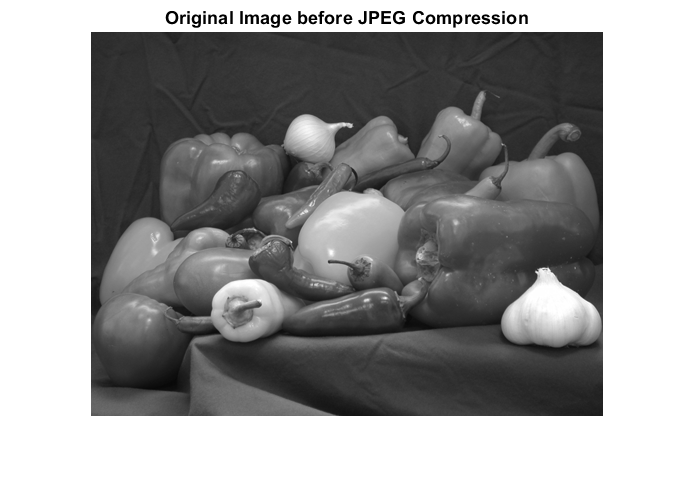

clear; clc;

x = imread("peppers.png");
QuantHeader = 2; % Low Compression (Check out Quantize.m for details)

% If the image is RGB, convert it to grayscale
if length(size(x)) > 2
    x = rgb2gray(x);
end

% Show the grayscale image before compression
imshow(x)
title("Original Image before JPEG Compression")

% Store the original dimensions of the image to be sent as headers
[m_org, n_org] = size(x);
fprintf("Original image dimensions: %d x %d.", size(x,1), size(x,2))

Original image dimensions: 384 x 512.

#### Zero Padding

The first step of JPEG Encoding is dividing the input image into 8 pixels by 8 pixels blocks. But to ensure that this step goes smoothly, the input image has to be zero padded to make sure its dimensions are indeed multiples of 8 and are equal.

x_input = ZeroPad(double(x), 8);
fprintf("Image dimensions after zero padding: %d x %d.", size(x_input,1), size(x_input,2))

Image dimensions after zero padding: 512 x 512.

*The following three steps are repeated for each of the 8-by-8 blocks:*

#### Discrete Cosine Transform

After padding and dividing the image, the Discrete Cosine Transform of each 8-by-8 block is taken to extract its frequency components.

#### Quantization

The DCT of each block is quantized according to the desired compression.

#### Zigzag Traversal

After quantization, the 2D DCT is turned into a 1D stream in order to be encoded and sent to the decoder. The traversal pattern we apply is a zigzag to ensure that the high frequencies, which were highly attenuated or cancelled during quantization, are grouped together in the end. This will be helpful when we apply run-length coding in the next step.

n = size(x_input,1);
x_1D = [];

for i = 1:n/8
    for j = 1:n/8
      % Divide the image into blocks of 8 by 8 pixels
      x_8by8 = x_input((i-1)*8+1 : i*8, (j-1)*8+1 : j*8);
      % Apply DCT to each block
      x_DCT = DCT_8by8(x_8by8);
      % Quantize the DCT according to the input compression rate
      x_Quantized = Quantize(x_DCT, QuantHeader);
      % Zigzag traverse each block and transform it into a 1D array
      x_Zigzaged = Zigzag(x_Quantized);
      % Concatenate all the 1D arrays into a long stream
      x_1D = [x_1D x_Zigzaged];
    end
end

fprintf("Length of the 1D array of pixels: %d.", length(x_1D))

Length of the 1D array of pixels: 262144.

#### Run-length Encoding

Because high frequencies are usually cancelled, the zigzag traversal leads to a long stream of zeroes at the end of its output. These zeroes can be run-length encoded to acheive a reasonable lossless compression.

% Collect all headers in one array and add it to the stream to be encoded
headers = [QuantHeader m_org n_org];
x_1D = [headers x_1D];

% Apply run-length encoding
x_runlength_en = RunlengthEncode(x_1D);

fprintf("Length of encoded 1D array of pixels: %d.", length(x_runlength_en))

Length of encoded 1D array of pixels: 70329.

#### Huffman Encoding

Lossless Huffman encoding is used to losslessly transform the values of the image pixels and the headers into a binary stream. I used my own impelementation of the Huffman Encoder. The encoder creates two files: one contains the table of codes and the other contains the stream of encoded bits.

characters = unique(x_runlength_en);
probs = GetProbabilities(x_runlength_en, characters);
code = HuffmanCreator(characters, probs);
X = HuffmanEncoder(characters, code, x_runlength_en);

## Second: JPEG Decoder

The JPEG decoder receives the encoded and compressed stream of bits and translates into the image and the headers which are used to properly construct the image.

Although I showcase the decoder here as separate steps, I attached the JPEG_Decoder function to perform all steps of the decoding as one module.

#### Huffman Decoding

Lossless Huffman decoding is used to losslessly transform the binary stream into the values of the image pixels and the headers. I used my own impelementation of the Huffman Decoder.

x_Huffman_de = HuffmanDecoder(characters, code, X);

#### Run-length Decoding

To retrieve the full stream of image values, we apply run-length decoding and separate the headers from the pixel stream.

% Apply run-length decoding
x_decoded = RunlengthDecode(x_Huffman_de);

% Extract the headers
QuantHeader = x_decoded(1);
m_org = x_decoded(2);
n_org = x_decoded(3);
x_decoded = x_decoded(4:end);

% Deduce the dimensions of the zero padded image
if n_org > m_org
    larger = n_org;
else
    larger = m_org;
end
n = 8 * ceil(larger/8);

*The following three steps are repeated for each of the 8-by-8 blocks:*

### Inverse Zigzag Traversal

Each 64 values from the decoded stream are reconstructed into an 8-by-8 block through inverse zigzag traversal.

#### Rescaling

The reconstructed 8-by-8 DCT blocks are rescaled by the same quantization tables they were quantized with during encoding to restore their values.

#### Inverse Discrete Cosine Transform

The IDCT is used to restore the image from the 8-by-8 DCT blocks.

x_output = zeros(n,n);

for i = 1:n/8
    for j = 1:n/8
      % Divide the stream of characters into arrays of 64 elements
      x_1D = x_decoded((i-1)*8*n+(j-1)*64+1 : (i-1)*8*n+j*64);
      % Convert the 1D array into a 2D 8-by-8 block
      x_block = InverseZigzag(x_1D);
      % Rescale the DCT using the same quantization table
      x_dequantized = InverseQuantize(x_block, QuantHeader);
      % Apply IDCT to retrieve the image block
      x_IDCT = IDCT_8by8(x_dequantized);
      % Concatenate all the 8-by-8 blocks into the image
      x_output((i-1)*8+1 : i*8, (j-1)*8+1 : j*8) = x_IDCT;
    end
end

The last step of JPEG decoding is cropping the image to get rid of any zero padding.

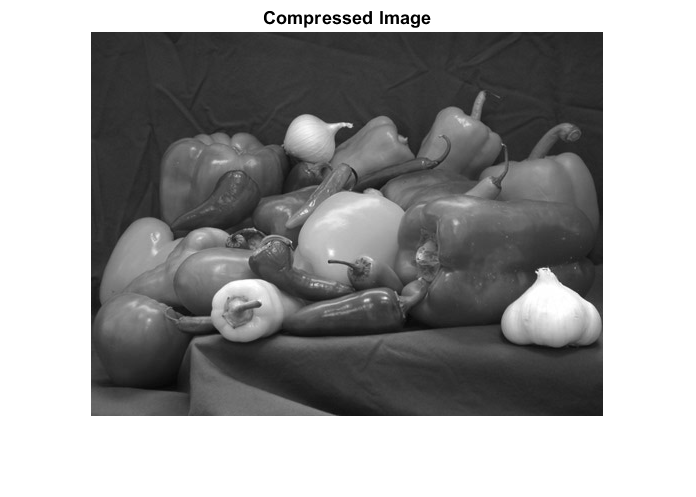

% Crop the zero padding using the original dimensions
x_output = uint8(x_output(1:m_org,1:n_org));

% Show the compressed image
imshow(x_output)
title("Compressed Image")

## III. Evaluation

#### First: Low Compression

Using the above code, we evaluate the compression and quality of the output image for low compression.

% Calculate number of bits in the input image
input_num_pixels = numel(x);
input_bits = 8 * input_num_pixels;

% Calculate number of bits in the coded stream
output_bits = numel(X);

fprintf("Compression Ratio for low compression: %d:1", floor(input_bits/output_bits))

Compression Ratio for low compression: 5:1

% Calculate the SSIM
SSIM = ssim(x_output, uint8(x));

fprintf("SSIM for low compression = %f", SSIM)

SSIM for low compression = 0.983576

#### Second: High Compression

We repeat the above evaluation for high and standard compressions. Here I use the JPEG_Encoder and JPEG_Decoder modules.

x_input = imread("peppers.png");
[X, HuffmanCodes] = JPEG_Encoder(x_input, "high");
title("Original Image before JPEG Compression")

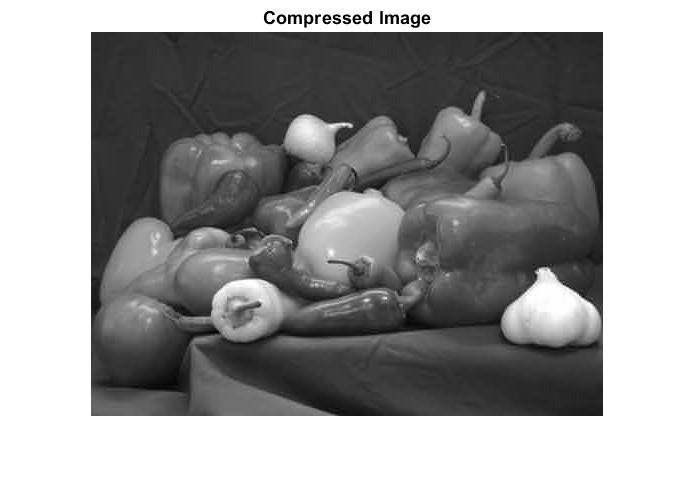

x_output = JPEG_Decoder(X, HuffmanCodes);
title("Compressed Image")

input_num_pixels = numel(rgb2gray(x_input));
input_bits = 8 * input_num_pixels;
output_bits = numel(X);
fprintf("Compression Ratio for high compression: %d:1", floor(input_bits/output_bits))

Compression Ratio for high compression: 14:1

SSIM = ssim(x_output, rgb2gray(x_input));
fprintf("SSIM for high compression = %f", SSIM)

SSIM for high compression = 0.942688

#### Third: Standard Compression

x_input = imread("peppers.png");
[X, HuffmanCodes] = JPEG_Encoder(x_input, "standard");
title("Original Image before JPEG Compression")

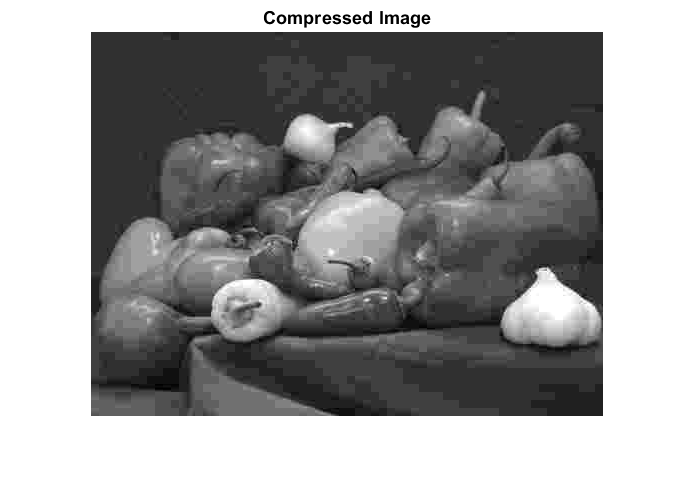

x_output = JPEG_Decoder(X, HuffmanCodes);
title("Compressed Image")

input_num_pixels = numel(rgb2gray(x_input));
input_bits = 8 * input_num_pixels;
output_bits = numel(X);
fprintf("Compression Ratio for standard compression: %d:1", floor(input_bits/output_bits))

Compression Ratio for standard compression: 27:1


SSIM = ssim(x_output, rgb2gray(x_input));
fprintf("SSIM for standard compression = %f", SSIM)

SSIM for standard compression = 0.846293

The standard compression image quality is even worse than the high quality. This is maybe due to the fact that the JPEG standard algorithm uses different coefficients for the DCT.

## VI. References

- The Manuscript Digitization Demonstration Project, *Compression*. [Online]. Available: [https://memory.loc.gov/ammem/pictel/mddp308.htm](https://memory.loc.gov/ammem/pictel/mddp308.htm). [Accessed: 10-Dec-2020].

- MathWorks, “ssim,” *Structural similarity (SSIM) index for measuring image quality - MATLAB*. [Online]. Available: [https://www.mathworks.com/help/images/ref/ssim.html](https://www.mathworks.com/help/images/ref/ssim.html). [Accessed: 10-Dec-2020]. 